# Data Transform

clear;clc
rng(42)

Data normalization

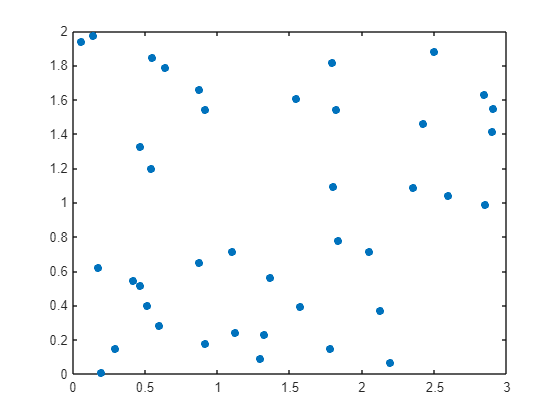

% Generate a 2-D random distribution
X = rand([40,2]);
scatter(X(:,1) * 3, X(:,2)*2,'filled')
xlim([0,3])
ylim([0,2])
box on

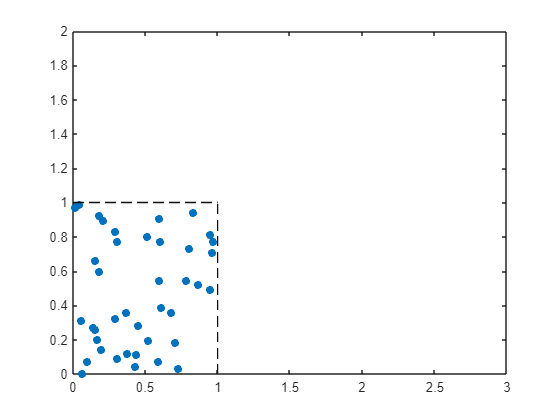

% Data normalization by scaling it down to a 1x1 region
figure,
hold on
scatter(X(:,1), X(:,2),'filled')
xlim([0,3])
ylim([0,2])
plot([0,1],[1,1],'--','Color','#101010')
plot([1,1],[0,1],'--','Color','#101010')
box on
hold off

Data standardization

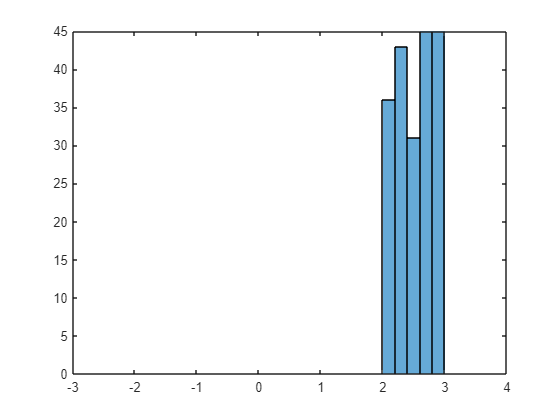

% Generate a random uniform distribution away from 0
X = rand(200,1) + 2;
histogram(X)
xlim([-3,4])

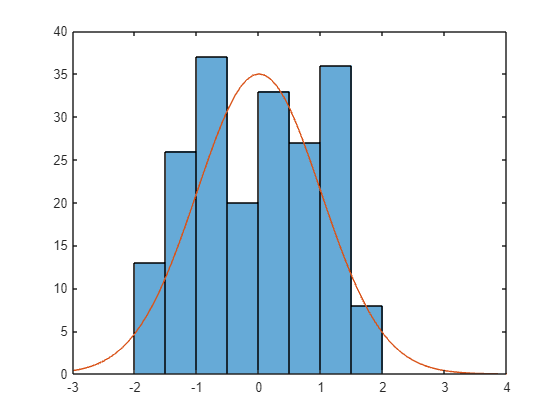

% Standardize the original data with its standard deviation and mean
X = (X - mean(X,1)) ./ std(X);
histogram(X)
xlim([-3,4])

% Gaussian ditribution for reference
hold on
x = -3:0.1:4;
y = gaussmf(x,[1 0]) * 35; % 1 is the standard deviation and 0 is the mean
plot(x,y)
hold off

Power transform - Box-Cox transform

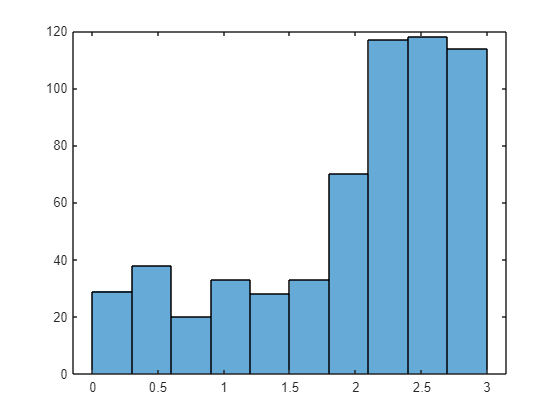

% Generating a non-Gaussian distributed data
X = [rand(400,1)+2; rand(100,1)+1; rand(100,1)];
histogram(X);

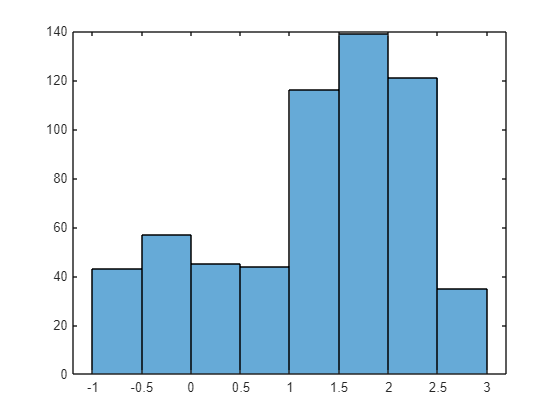

% Draw the histogram of the transformed distribution
histogram(boxcox(X));